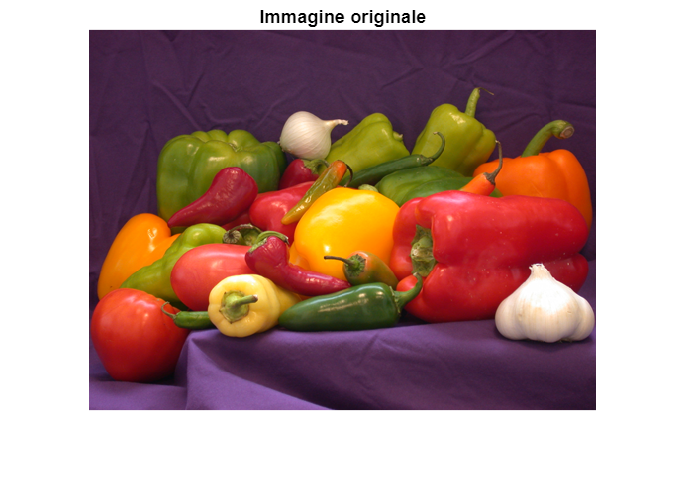

%--------------------------%
% Script: Notch Filter su Immagini RGB con Metriche No‐Reference
%          (stima automatica delle frequenze fx, fy e confronto con quelle reali)
%--------------------------%

% 1) Carica l’immagine RGB e normalizzala in [0,1]
I_orig_rgb = im2double(imread('peppers.png'));
[M, N, C]    = size(I_orig_rgb);   % C = 3 per RGB

% 2) Definisci e aggiungi rumore periodico su ciascun canale
A   = 0.05;      % ampiezza del rumore
fx_true  = 0.05; % frequenza orizzontale reale (cicli/pixel)
fy_true  = 0.07; % frequenza verticale reale (cicli/pixel)
phi = 0;         % fase iniziale

[X, Y] = meshgrid(1:N, 1:M);
noise2D = A * sin(2*pi*(fx_true*X + fy_true*Y) + phi);
noise3Ch = repmat(noise2D, [1, 1, C]);

I_noisy_rgb = I_orig_rgb + noise3Ch;
I_noisy_rgb = min(max(I_noisy_rgb, 0), 1);

% Visualizza immagine originale e con rumore
figure;
imshow(I_orig_rgb);
title("Immagine originale");

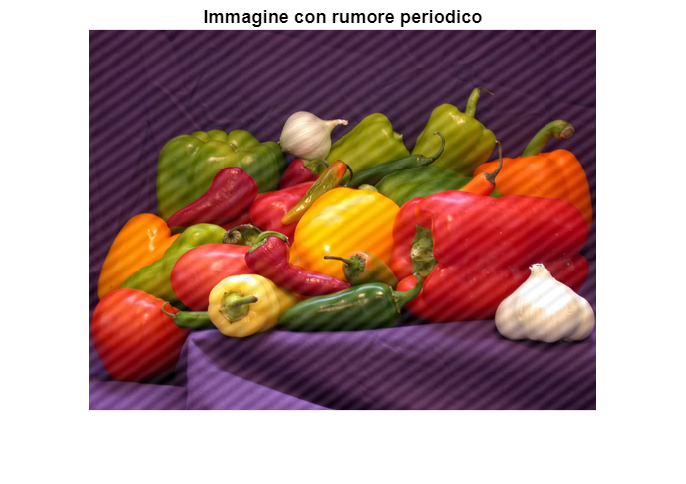

figure;
imshow(I_noisy_rgb);
title("Immagine con rumore periodico");


% 3) Calcola FFT shiftata per ciascun canale
Fshift_rgb = zeros(M, N, C);
for ch = 1:C
    F = fft2(I_noisy_rgb(:,:,ch));
    Fshift_rgb(:,:,ch) = fftshift(F);
end

% 4) Stima automatica delle coordinate dei picchi (maggiore intensità)
magSum = zeros(M, N);
for ch = 1:C
    magSum = magSum + abs(Fshift_rgb(:,:,ch));
end
magAvg = magSum / C;

% Maschera intorno al DC (±5 px) per evitare di rilevarlo
u_center = floor(N/2) + 1;
v_center = floor(M/2) + 1;
dc_half = 5;
u_min_dc = max(u_center - dc_half, 1);
u_max_dc = min(u_center + dc_half, N);
v_min_dc = max(v_center - dc_half, 1);
v_max_dc = min(v_center + dc_half, M);
magAvg(v_min_dc:v_max_dc, u_min_dc:u_max_dc) = 0;

% Trova il primo picco (positivo)
[~, idx1] = max(magAvg(:));
[v_pos, u_pos] = ind2sub([M, N], idx1);

% Elimina il primo picco per trovare il secondo
magAvg(idx1) = 0;
[~, idx2] = max(magAvg(:));
[v_neg, u_neg] = ind2sub([M, N], idx2);

% 5) Calcolo delle frequenze stimate (in cicli/pixel)
dx_pos = u_pos - u_center;  % offset orizzontale dal centro
dy_pos = v_pos - v_center;  % offset verticale dal centro

fx_est = abs(dx_pos) / N;
fy_est = abs(dy_pos) / M;

fprintf('Frequenze rilevate:\n');

Frequenze rilevate:


fprintf('  fx_est = %.4f cicli/pixel\n', fx_est);

  fx_est = 0.0508 cicli/pixel


fprintf('  fy_est = %.4f cicli/pixel\n\n', fy_est);

  fy_est = 0.0703 cicli/pixel




fprintf('Frequenze reali:\n');

Frequenze reali:


fprintf('  fx_true = %.4f cicli/pixel\n', fx_true);

  fx_true = 0.0500 cicli/pixel


fprintf('  fy_true = %.4f cicli/pixel\n\n', fy_true);

  fy_true = 0.0700 cicli/pixel




% 6) Definisci i valori di 'd' da provare
D_values = [3, 5, 7, 9, 11, 13];
numD     = numel(D_values);

% 7) Calcola metriche no‐reference sull’immagine originale
niqe_orig    = niqe(I_orig_rgb);
brisque_orig = brisque(I_orig_rgb);
piqe_orig    = piqe(I_orig_rgb);

fprintf('Metriche su Immagine Originale:\n');

Metriche su Immagine Originale:


fprintf('  NIQE    = %.4f\n', niqe_orig);

  NIQE    = 3.1050


fprintf('  BRISQUE = %.4f\n', brisque_orig);

  BRISQUE = 29.6356


fprintf('  PIQE    = %.4f\n\n', piqe_orig);

  PIQE    = 27.0076




% Prealloca array per le metriche e le immagini filtrate
NIQEs    = zeros(1, numD);
BRISQUEs = zeros(1, numD);
PIQEs    = zeros(1, numD);
I_filt_all_rgb = cell(1, numD);

% 8) Loop su ciascun valore di d: filtro notch + calcolo metriche
for k = 1:numD
    d = D_values(k);
    
    % Costruisci la maschera notch 2D
    mask2D = ones(M, N);
    
    % Picco positivo
    umin  = max(u_pos - d, 1);
    umax  = min(u_pos + d, N);
    vmin  = max(v_pos - d, 1);
    vmax  = min(v_pos + d, M);
    mask2D(vmin:vmax, umin:umax) = 0;
    
    % Picco negativo
    umin2 = max(u_neg - d, 1);
    umax2 = min(u_neg + d, N);
    vmin2 = max(v_neg - d, 1);
    vmax2 = min(v_neg + d, M);
    mask2D(vmin2:vmax2, umin2:umax2) = 0;
    
    % Replica la maschera per i 3 canali
    mask_rgb = repmat(mask2D, [1, 1, C]);
    
    % Applica la maschera notch e ricostruisci ogni canale
    I_rec_rgb = zeros(M, N, C);
    for ch = 1:C
        Fshift_notched = Fshift_rgb(:,:,ch) .* mask2D;
        F_notched      = ifftshift(Fshift_notched);
        I_rec_ch       = real(ifft2(F_notched));
        I_rec_ch       = min(max(I_rec_ch, 0), 1);
        I_rec_rgb(:,:,ch) = I_rec_ch;
    end
    
    % Memorizza l’immagine ricostruita
    I_filt_all_rgb{k} = I_rec_rgb;
    
    % Calcola metriche no-reference sull’immagine RGB ricostruita
    NIQEs(k)    = niqe(I_rec_rgb);
    BRISQUEs(k) = brisque(I_rec_rgb);
    PIQEs(k)    = piqe(I_rec_rgb);
    
    % Stampa a video le metriche per questo valore di d
    fprintf('d = %d: NIQE = %.4f, BRISQUE = %.4f, PIQE = %.4f\n', ...
        d, NIQEs(k), BRISQUEs(k), PIQEs(k));
end

d = 3: NIQE = 3.4117, BRISQUE = 36.2399, PIQE = 31.1060
d = 5: NIQE = 3.3946, BRISQUE = 32.5531, PIQE = 32.0340
d = 7: NIQE = 3.5623, BRISQUE = 30.4741, PIQE = 29.6027
d = 9: NIQE = 3.3721, BRISQUE = 29.8805, PIQE = 29.4253
d = 11: NIQE = 3.4382, BRISQUE = 29.3178, PIQE = 28.5716
d = 13: NIQE = 3.2944, BRISQUE = 29.4958, PIQE = 28.7195


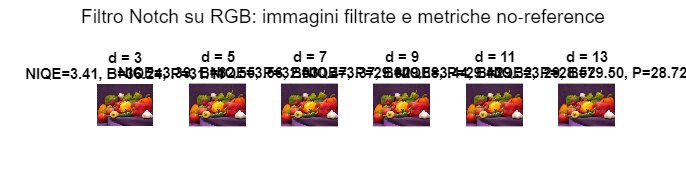


% 9) Visualizzazione dei risultati (immagini)
figure('Position',[100 100 1400 400]);
for k = 1:numD
    subplot(1, numD, k);
    imshow(I_filt_all_rgb{k});
    title(sprintf('d = %d\nNIQE=%.2f, B=%.2f, P=%.2f', ...
        D_values(k), NIQEs(k), BRISQUEs(k), PIQEs(k)));
end
sgtitle('Filtro Notch su RGB: immagini filtrate e metriche no‐reference');

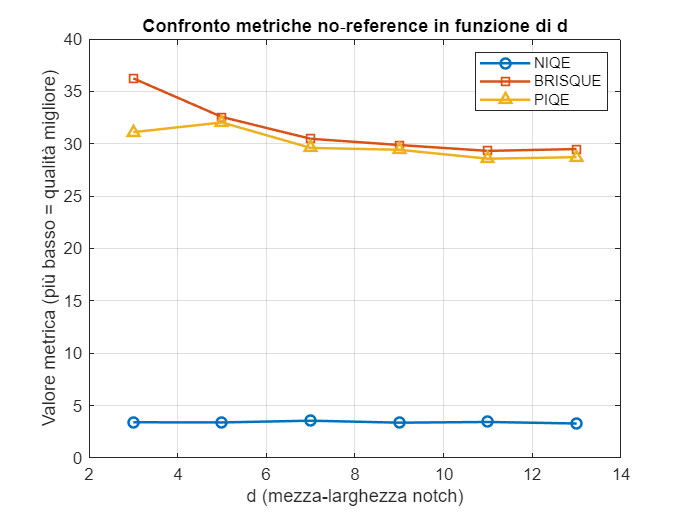


% 10) Grafici delle metriche in funzione di d
figure;
plot(D_values, NIQEs,   '-o', 'LineWidth', 1.5); hold on;
plot(D_values, BRISQUEs,'-s', 'LineWidth', 1.5);
plot(D_values, PIQEs,   '-^', 'LineWidth', 1.5);
hold off;
grid on;
xlabel('d (mezza-larghezza notch)');
ylabel('Valore metrica (più basso = qualità migliore)');
legend('NIQE','BRISQUE','PIQE','Location','northeast');
title('Confronto metriche no‐reference in funzione di d');